# Enzyme kinetics within our GRASP: A computational platform for building kinetic models of cellular metabolism

**Marta R. A. Matos, Pedro A. Saa, Nicholas Cowie, Svetlana Volkova, Marina de Leeuw, Lars K. Nielsen**

The aim of this tutorial is to illustrate the execution and use of GRASP for building and analyzing kinetic models of metabolism. This tutorial demonstrates how to sample around a thermodynamically feasible (random) reference state and perform MCA in a simple model of the adenine nucleotide cycle (Valero et al. 2006). This model contains 3 reactions, 3 balanced metabolites and 6 external metabolites (not balanced). Also, this model has 1 moeity conservation relation.

### 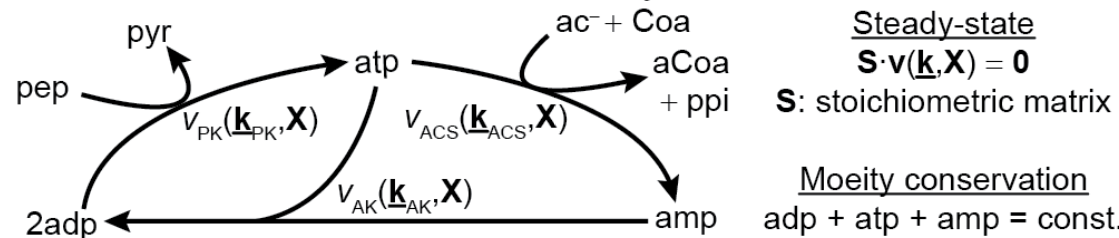

**Figure 1.** Illustrative scheme of the adenine nucleotide cycle.

## Tutorial 01: Sampling from the prior (GRASP mode)

Clear all variables and add functions to path. Note that you need to be in the tutorials folder.

clear, close all
rng('default');                 % for reproducibility
addpath(fullfile('..', 'matlab_code', 'analysisFxns'), ...
        fullfile('..', 'matlab_code', 'ensembleFxns'), ...
        fullfile('..', 'matlab_code', 'patternFxns'));

Set the maximum number of models to sample. This is particularly important when simulating the model from the prior (i.e., no experimental data defined)

maxNumberOfSamples = 1e5;

Set a threshold for the minimum Jacobian eigenvalue of the system. Models with values below this threshold will be discarded due to unstability criteria.

eigThreshold = 1e-5;

Define the model ID name, input and output files. These paths are necessary for executing GRASP.

modelID = 'tutorial_01_adenine_cycle';
inputFile  = fullfile('..', 'io', 'input', modelID);
outputFile = fullfile('..', 'io', 'output', [modelID, '.mat']);

Build the kinetic ensemble. In this case, we will build an ensemble of 100 models. To accelerate computations, we set the parellel mode to 'on' in the specification file. Two cores will be assigned to these calculations, although more can be assigned if desired.

tic
ensemble = buildEnsemble(inputFile, outputFile, maxNumberOfSamples, eigThreshold);

General information loaded.
Flux data computed and loaded.
The fluxes and Gibbs energies are consistent.
Flux directions are consistent.
Gibbs energy directions are consistent.
The initial point obtained from TMFA is feasible and valid for starting the sampler.
Thermodynamic data computed and loaded.
Metabolomics data loaded.
No previous prior for model 1
Proteomics and exchange data loaded and consistent.
Kinetic information loaded and kinetic model built: Structure 1.
Ensemble structure ready.
Ensemble successfully initialized.
Sampling fluxes
Starting parallel pool (parpool) using the 'local' profile ...
connected to 2 workers.
Sampling Gibbs energies
Starting parallel pool (parpool) using the 'local' profile ...
connected to 2 workers.
Fluxes and Gibbs energies successfully sampled
Running initial sampler.
Starting parallel pool (parpool) using the 'local' profile ...
connected to 2 workers.
Sampling model: 4
Sampling model: 12
Sampling model: 3
Sampling model: 11
Sampling model: 2

Error using buildEnsemble>(parfor consume)
Unable to perform assignment because the size of the left side is 4-by-0 and the size of the right side is 4-by-1.

Error in buildEnsemble (line 205)
        parfor ix = (sampleCount+1):(sampleCount+nSamples)

toc


Using this ensemble, we compute flux and metabolite control coefficients and visualize the final results

mcaResults = controlAnalysis(ensemble,1);
categories = {};         % Displays MCA results for all the reactions
plotControlAnalysis(mcaResults, ensemble, categories);

## References

- Valero E, Varón R, García-Carmona F. (2006) A kinetic study of a ternary cycle between adenine nucleotides. The FEBS Journal **273**: 3598–3613